# Calcular el area de un cícrculo de radio 1 centrado en el origen

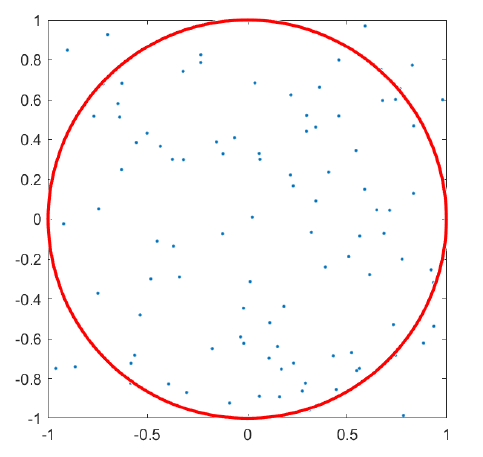

- Generar $n$ puntos aleatorios en el plano $\left(x,y\right)$, donde $x$ e $y$ son distribuidos uniformemente en el intervalo $\left\lbrack -1,1\right\rbrack$.

- Contar el número de puntos que se encuentran en el interior del cícrculo

- Estimar el área del círculo como: $A=R*\frac{n_c }{n}$, donde $R$ es el área del rectángulo $\left\lbrack -1,1\right\rbrack \times \left\lbrack -1,1\right\rbrack$. En este caso, $R=4$.

clc
clear all
r = 1;              % radio del circulo
nc=0;               % aciertos
n=1000;            % numero de intentos
interval=[-r,r]    % definición del

interval =     -1     1


R=diff(interval)^2

R = 4


diff(interval)

ans = 2

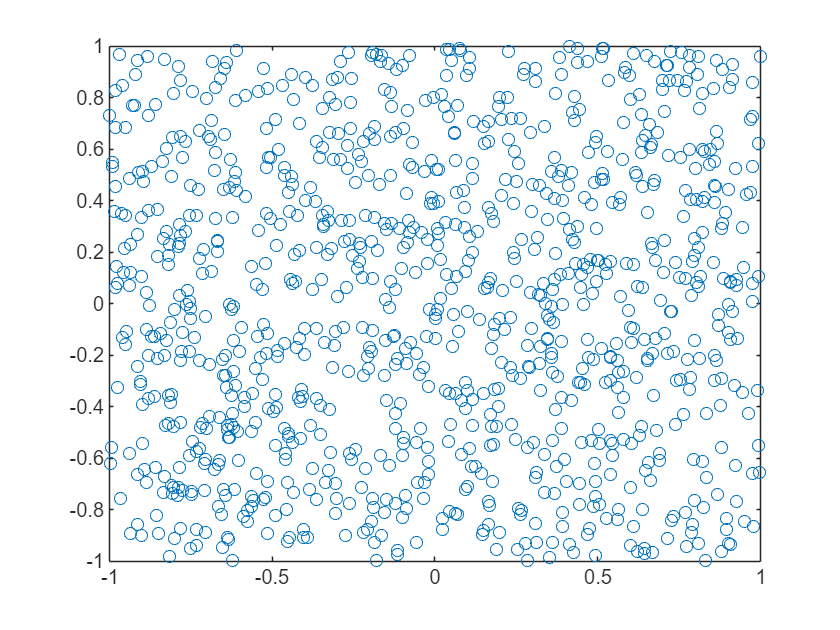


% generar puntos aleatorios uniformemente distribuidos en [-r,r]
P = -1 + rand(2,n).*diff(interval);
figure;
plot(P(1,:),P(2,:),'o')


% identificar los puntos que se encuentran dentro del circulo
idx = vecnorm(P)<=r; 
nc=sum(idx);
vol_esti=R*nc/n;
%fprintf('La probabilidad de éxito es:%d\n',nc/n);

fprintf('El área del circulo es:%d\n',vol_esti)

El área del circulo es:3.236000e+00


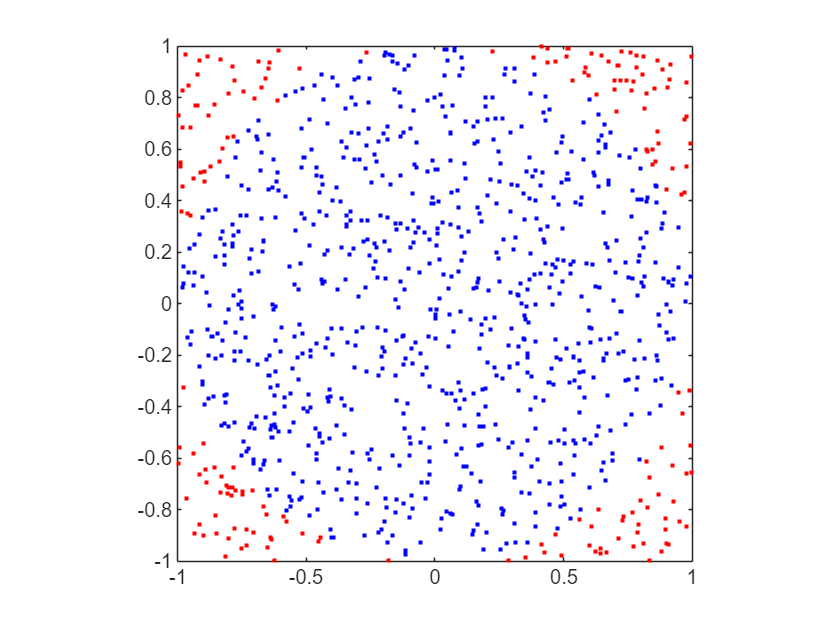

P=P';
figure;
plot(P(:,1),P(:,2),'r.');hold on
plot(P(idx,1),P(idx,2),'b.')
axis square